6. Programmatically plot 50 circles in 3D with radii ranging from 1 to 100 with increments of 2, and the z-axis separation of 1. 

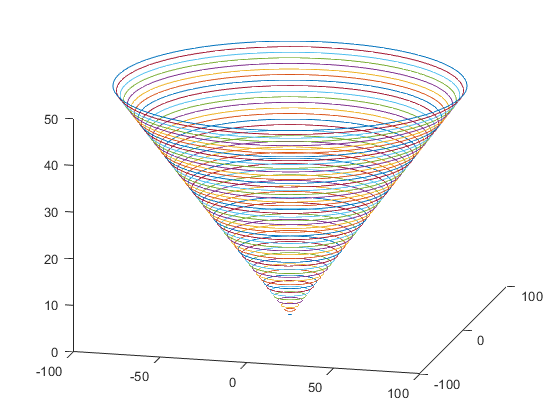

radii = 1:2:100;
height = 1:numel(radii);

figure
circle3D(radii,height);
view([14.1 21.2])
saveas(gcf,'circles3D.svg')
saveas(gcf,'circles3D.png')

7. Assume a sampling rate of 1000 samples/s, create a new figure, split it into 4 separate plots (2x2), scale and optimize each plot as you see fit after you

a. Plot the unit step function in continuous time and discrete time 

b. Plot the unit impulse function in continuous time and discrete time 

c. Plot the standard ramp function in continuous time and discrete time 

d. Plot a square wave in continuous time and discrete time

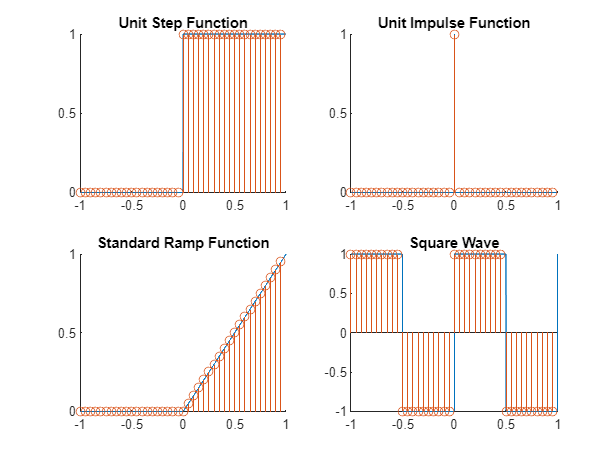

t_min = -1;
t_max = 1;
t_size = abs(t_min) + abs(t_max);
sample_rate = 1000;
tot_samples=sample_rate*t_size;
t = linspace(t_min,t_max,tot_samples);

ds_factor = 50; %downsampling dactor

%declare functions
unitstep = t>=0;
impulse = t==5.002501250625312e-04; %closest value to zero when downsampled
ramp = t.*unitstep;
sqwave = square(2*pi*t); %frequency ~1 Hz

figure
subplot(221)
title('Unit Step Function')
plot_signal(t, unitstep, ds_factor)
subplot(222)
title('Unit Impulse Function')
plot_signal(t, impulse, ds_factor)
subplot(223)
title('Standard Ramp Function')
plot_signal(t, ramp, ds_factor)
subplot(224)
title('Square Wave')
plot_signal(t, sqwave, ds_factor)

## Amplitude Modulator

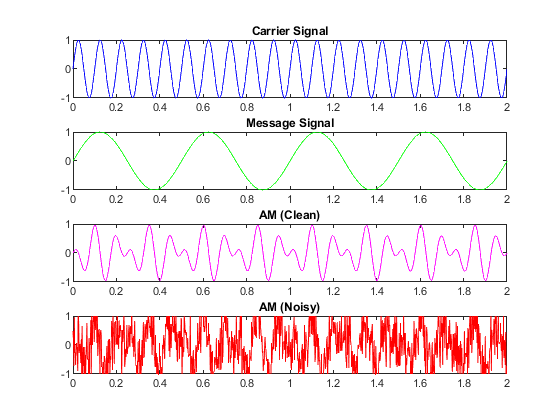

t_min = 0;
t_max = 2;
t_size = abs(t_min) + abs(t_max);
sample_rate = 500;
tot_samples=sample_rate*t_size;
t = linspace(t_min,t_max,tot_samples);

fc = 10; %carrier frequency
fm = 2; %message frequency
carr = sin(2*pi*fc*t);
msg = sin(2*pi*fm*t);
AM_clean = ammod(msg,fc,sample_rate);
AM_noise = awgn(AM_clean,5);

figure
for k = 1:length(t)
    if k==length(t)
        break
    end

    axis([0 2 -1 1])
    subplot(411)
    title('Carrier Signal')
    plot(t(k:k+1),carr(k:k+1),'b')
    hold on

    axis([0 2 -1 1])
    subplot(412)
    title('Message Signal')
    plot(t(k:k+1),msg(k:k+1),'g')
    hold on
    
    axis([0 2 -1 1])
    subplot(413)
    title('AM (Clean)')
    plot(t(k:k+1),AM_clean(k:k+1),'m')
    hold on

    axis([0 2 -1 1])
    subplot(414)
    title('AM (Noisy)')
    plot(t(k:k+1),AM_noise(k:k+1),'r')
    hold on
    
    drawnow
end

Functions for assignment

function circle3D(r,z)
    hold on
    for i = 1:numel(r)
        th = 0:pi/50:2*pi;
        x = r(i) * cos(th);
        y = r(i) * sin(th);
        h = plot3(x, y, zeros(1,numel(x))+z(i));
    end
    hold off
end

function plot_signal(time,signal,ds_factor)
    %downsample signal
    time_down = downsample(time,ds_factor);
    signal_down = downsample(signal,ds_factor);
    
    %plot continuous and discrete functions
    hold on
    plot(time, signal)
    stem(time_down, signal_down)
    hold off
end